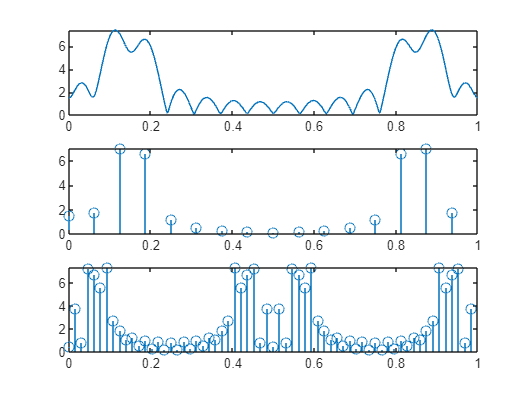

clc
clear

n = 0:15;
x = sin(0.25*pi*n)+sin(0.34*pi*n);
L1 = 0:15;
dft_16 = fft(x,16);

for m=1:32
if mod(m,2)==0
y(m) = sin(0.25*pi*m/2)+sin(0.34*pi*m/2);
else
y(m)=0;
end
end

Ly = 0:63;
dft_y = fft (y,64);
nx=0:15;
K=512;
dw=2*pi/K;
k=0:511;
X=x*exp(1i*dw*nx'*k);

subplot (3, 1,1);
plot (k*dw/(2*pi),abs (X));

subplot (3, 1, 2);
stem(L1/16,abs(dft_16));
subplot (3, 1, 3);
stem(Ly/64, abs(dft_y));

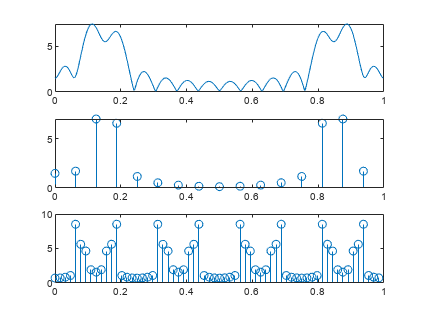

n = 0:15;
x = sin(0.25*pi*n)+sin(0.34*pi*n);
L1 = 0:15;
dft_16 = fft(x,16);

for m=1:64
if mod(m,4)==0
y(m) = sin(0.25*pi*m/2)+sin(0.34*pi*m/2);
else
y(m) = 0;
end
end

Ly = 0:63;
dft_y = fft (y, 64);
nx = 0: 15;
K = 512;
dw = 2*pi/K;
k = 0:511;
X = x*exp(1i*dw*nx'*k);
subplot (3, 1,1)
plot (k*dw/(2*pi),abs (X));

subplot (3, 1, 2)
stem(L1/16,abs(dft_16))
subplot (3, 1, 3)
stem(Ly/64, abs(dft_y))